# MTH 4800 Numerical Analysis I Programming Assignment 5

## Jarred Maestas

    1. The gamma function is defined by$\Gamma(x)=\int_{0}^\infty t^{x-1}e^{-t}dt, x >0$.

    It is known that for integer numbers the function has the value $\Gamma(n) = (n - 1)! = 1 \cdot 2 \cdot 3 . . . (n - 1), (0! = 1).$

    Thus, for example, $(1, 1), (2, 1), (3, 2), (4, 6), (5, 24)$ can be used as data points for an interpolating polynomial.

        (a). Write a script that computes the polynomial interpolant of degree four that passes through the above 5 data points.

function [coeffs, dd_table] = divided_differences(x_vals, y_vals)
% divided_differences - Newton's Divided Differences interpolation method
%
% Inputs:
%   x_vals - vector of x-coordinates (n+1 data points)
%   y_vals - vector of function values f(x_i) corresponding to x_vals
%
% Outputs:
%   coeffs   - vector of divided difference coefficients [f[x0], f[x0,x1], ...]
%   dd_table - full divided differences table for analysis

    % Input validation
    if length(x_vals) ~= length(y_vals)
        error('x_vals and y_vals must have the same length');
    end
    
    n = length(x_vals);
    
    % Initialize divided differences table
    dd_table = zeros(n, n);
    
    % Extract coefficients from top diagonal of divided differences table
    % The first row contains the Newton form coefficients: f[x0], f[x0,x1], etc
    dd_table(:, 1) = y_vals(:);
    
    % Compute higher order divided differences using recursive formula:
    % f[x_i, ..., x_{i+j}] = (f[x_{i+1}, ..., x_{i+j}] - f[x_i, ..., x_{i+j-1}]) / (x_{i+j} - x_i)
    for j = 2:n  % j represents column (order + 1)
        for i = 1:(n-j+1)  % i represents row (starting index)
            numerator = dd_table(i+1, j-1) - dd_table(i, j-1);
            denominator = x_vals(i+j-1) - x_vals(i);
            dd_table(i, j) = numerator / denominator;
        end
    end
    
    % Extract coefficients from top diagonal
    coeffs = dd_table(1, :);
end

function p_val = evaluate_dd(x_vals, coeffs, x_eval)
% evaluate_dd - Evaluates Newton's divided differences polynomial
%
% Inputs:
%   x_vals - original x-coordinates used for interpolation
%   coeffs - divided difference coefficients
%   x_eval - points at which to evaluate polynomial
%
% Output:
%   p_val - polynomial values at x_eval points

    % Initialize output array to match input size
    p_val = zeros(size(x_eval));
    n = length(coeffs);
    
    % Evaluate polynomial at each requested point
    for k = 1:length(x_eval)
        x = x_eval(k);
        
        % Nested evaluation using Newton's form
        p = coeffs(1);  % Start with f[x0]
        
        % Build product terms incrementally
        product_term = 1;
        for i = 2:n
            product_term = product_term * (x - x_vals(i-1));
            p = p + coeffs(i) * product_term;
        end
        
        % Store computed value
        p_val(k) = p;
    end
end

% Problem setup for Divided Differences method testing
x_data = [1, 2, 3, 4, 5];
y_data = [1, 1, 2, 6, 24];  % [0!, 1!, 2!, 3!, 4!]

%% Compute Divided Differences
[coeffs, dd_table] = divided_differences(x_data, y_data);

% Construct polynomial string representation
poly_str = sprintf('p(x) = %.6f', coeffs(1));
for i = 2:length(coeffs)
    if coeffs(i) >= 0
        poly_str = [poly_str sprintf(' + %.6f', coeffs(i))];
    else
        poly_str = [poly_str sprintf(' - %.6f', abs(coeffs(i)))];
    end
    
    % Add product terms (x - x_0)(x - x_1)...(x - x_{i-2})
    for j = 1:(i-1)
        poly_str = [poly_str sprintf('(x - %.1f)', x_data(j))];
    end
end

fprintf('Degree 4 interpolating polynomial: %s\n', poly_str);

Degree 4 interpolating polynomial: p(x) = 1.000000 + 0.000000(x - 1.0) + 0.500000(x - 1.0)(x - 2.0) + 0.333333(x - 1.0)(x - 2.0)(x - 3.0) + 0.375000(x - 1.0)(x - 2.0)(x - 3.0)(x - 4.0)



dd_table

dd_table =     1.0000         0    0.5000    0.3333    0.3750
    1.0000    1.0000    1.5000    1.8333         0
    2.0000    4.0000    7.0000         0         0
    6.0000   18.0000         0         0         0
   24.0000         0         0         0         0


        (b). Write a program that computes a cubic spline to interpolate the same data.

function g = cubic_spline(x, f, bc, xt)
% cubic_spline - Compute cubic spline interpolation
%
% Inputs:
% x  - vector of x-coordinates (knot points)
% f  - vector of function values at x
% bc - boundary condition vector [val1, val2, type] where:
%      type = 1: clamped (val1, val2 are derivative values at endpoints)
%      type = 2: natural (val1, val2 are second derivative values at endpoints)
%      type = NaN: default natural spline (second derivatives = 0)
% xt - evaluation points
%
% Output:
% g  - interpolated values at xt points

    % Input validation
    if length(x) ~= length(f)
        error('x and f must have the same length');
    end
    
    n = length(x) - 1;  % Number of spline segments
    
    % Initialize coefficient matrix A and right-hand side vector B
    A = zeros(4*n, 4*n);
    B = zeros(4*n, 1);
    
    % Pre-compute interval widths for efficiency
    h = diff(x);
    
    % Build the linear system for each spline segment
    for i = 1:n
        % Constraint 1: S_i(x_i) = f_i (function value at left endpoint)
        A(4*i-3, 4*i-3:4*i) = [1, 0, 0, 0];
        B(4*i-3) = f(i);
        
        % Constraint 2: S_i(x_{i+1}) = f_{i+1} (function value at right endpoint)
        A(4*i-2, 4*i-3:4*i) = [1, h(i), h(i)^2, h(i)^3];
        B(4*i-2) = f(i+1);
        
        if i < n  % Interior segments - apply continuity constraints
            % Constraint 3: First derivative continuity S'_i(x_{i+1}) = S'_{i+1}(x_{i+1})
            A(4*i-1, 4*i-3:4*i+4) = [0, 1, 2*h(i), 3*h(i)^2, 0, -1, 0, 0];
            B(4*i-1) = 0;
            
            % Constraint 4: Second derivative continuity S''_i(x_{i+1}) = S''_{i+1}(x_{i+1})
            A(4*i, 4*i-3:4*i+4) = [0, 0, 2, 6*h(i), 0, 0, -2, 0];
            B(4*i) = 0;
        end
    end
    
    % Apply boundary conditions for last segment
    if length(bc) >= 3 && ~isnan(bc(3))
        if bc(3) == 1  % Clamped boundary conditions (specified first derivatives)
            % Left boundary: S'_1(x_1) = bc(1)
            A(4*n-1, 1:4) = [0, 1, 0, 0];
            B(4*n-1) = bc(1);
            
            % Right boundary: S'_n(x_{n+1}) = bc(2)
            A(4*n, 4*n-3:4*n) = [0, 1, 2*h(n), 3*h(n)^2];
            B(4*n) = bc(2);
            
        elseif bc(3) == 2  % Natural boundary conditions (specified second derivatives)
            % Left boundary: S''_1(x_1) = bc(1)
            A(4*n-1, 1:4) = [0, 0, 2, 0];
            B(4*n-1) = bc(1);
            
            % Right boundary: S''_n(x_{n+1}) = bc(2)
            A(4*n, 4*n-3:4*n) = [0, 0, 2, 6*h(n)];
            B(4*n) = bc(2);
        end
    else
        % Default: Natural spline (zero second derivatives at endpoints)
        A(4*n-1, 1:4) = [0, 0, 2, 0];
        A(4*n, 4*n-3:4*n) = [0, 0, 2, 6*h(n)];
        B(4*n-1) = 0;
        B(4*n) = 0;
    end
    
    % Solve the linear system for spline coefficients
    C = A \ B;
    
    % Evaluate the spline at query points
    m = length(xt);
    g = zeros(size(xt));
    
    for i = 1:m
        % Find which segment contains the evaluation point
        for j = 1:n
            if j == n  % Last segment - include right endpoint
                if xt(i) >= x(j) && xt(i) <= x(j+1)
                    % Calculate offset from left endpoint of segment
                    xh = xt(i) - x(j);
                    
                    % Evaluate cubic polynomial: a + b*xh + c*xh^2 + d*xh^3
                    coeff_idx = 4*j - 3;
                    g(i) = C(coeff_idx) + C(coeff_idx+1)*xh + C(coeff_idx+2)*xh^2 + C(coeff_idx+3)*xh^3;
                    break;
                end
            else  % Interior segments - exclude right endpoint to avoid overlap
                if xt(i) >= x(j) && xt(i) < x(j+1)
                    % Calculate offset from left endpoint of segment
                    xh = xt(i) - x(j);
                    
                    % Evaluate cubic polynomial: a + b*xh + c*xh^2 + d*xh^3
                    coeff_idx = 4*j - 3;
                    g(i) = C(coeff_idx) + C(coeff_idx+1)*xh + C(coeff_idx+2)*xh^2 + C(coeff_idx+3)*xh^3;
                    break;
                end
            end
        end
    end
end

%% Define evaluation points
x_eval = linspace(1, 5, 100);

% Using natural boundary conditions (second derivatives = 0 at endpoints)
% Justification: Natural splines are appropriate when we have no information
% about the derivative behavior at the boundaries. They minimize curvature
% and avoid imposing artificial constraints at the endpoints, which is 
% suitable for the gamma function where derivative information isn't provided.
bc_natural = [0, 0, 2];
y_natural = cubic_spline(x_data, y_data, bc_natural, x_eval);

%% Compute Cubic Spline with Clamped Boundary Conditions  
% Estimate derivatives using finite differences
left_deriv = (-3*y_data(1) + 4*y_data(2) - y_data(3)) / 2;  % forward difference
right_deriv = (3*y_data(5) - 4*y_data(4) + y_data(3)) / 2;   % backward difference
bc_clamped = [left_deriv, right_deriv, 1];
y_clamped = cubic_spline(x_data, y_data, bc_clamped, x_eval);

        (c). Plot the two interpolants you found on the same graph, along with a plot of the gamma function

itself, which can be produced using the MATLAB command gamma.

        (d) Plot the errors in the two interpolants on the same graph. What are your observations? Discuss these approximations.

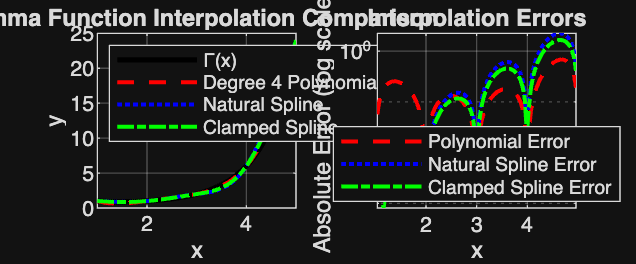

%% Compute Polynomial Interpolant (from previous section)
[coeffs, ~] = divided_differences(x_data, y_data);
y_poly = evaluate_dd(x_data, coeffs, x_eval);

%% Plot Interpolants vs Actual Gamma Function
figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
y_gamma = gamma(x_eval);
plot(x_eval, y_gamma, 'k-', 'LineWidth', 2, 'DisplayName', 'Γ(x)');
hold on;
plot(x_eval, y_poly, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Degree 4 Polynomial');
plot(x_eval, y_natural, 'b:', 'LineWidth', 1.5, 'DisplayName', 'Natural Spline');
plot(x_eval, y_clamped, 'g-.', 'LineWidth', 1.5, 'DisplayName', 'Clamped Spline');

xlabel('x');
ylabel('y');
title('Gamma Function Interpolation Comparison');
legend('Location', 'northwest');
grid on;
axis([1 5 0 25]);

%% Plot Interpolant Errors
subplot(1, 2, 2);
error_poly = abs(y_gamma - y_poly);
error_natural = abs(y_gamma - y_natural);
error_clamped = abs(y_gamma - y_clamped);

semilogy(x_eval, error_poly, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Polynomial Error');
hold on;
semilogy(x_eval, error_natural, 'b:', 'LineWidth', 1.5, 'DisplayName', 'Natural Spline Error');
semilogy(x_eval, error_clamped, 'g-.', 'LineWidth', 1.5, 'DisplayName', 'Clamped Spline Error');

xlabel('x');
ylabel('Absolute Error (log scale)');
title('Interpolation Errors');
legend('Location', 'best');
grid on;

            - The error plot reveals that all three interpolation methods achieve errors between $10^{-3}$ and $10^0$, with the degree 4 polynomial exhibiting significant oscillatory behavior characteristic of the Runge phenomenon, particularly in the intervals $[2,3]$ and $[4,5] $ where errors reach approximately $1.0$ near $x = 4.5$. In contrast, both cubic spline methods demonstrate superior stability and accuracy, with the clamped spline performing slightly better than the natural spline throughout most of the domain, especially near the boundaries where the specified derivative conditions help capture the rapidly increasing behavior of the gamma function. The piecewise nature of splines avoids the global oscillations that plague high-degree polynomial interpolation, making them the preferable choice for this problem. However, all methods struggle somewhat with the gamma function's exponential growth near $x = 5$, suggesting that additional data points or a transformation such as log-scale interpolation would improve accuracy for applications requiring higher precision.

    2. Consider interpolating the data $\begin{array}{|c|c|c|c|c|c|c|c|}
\hline
x & 0.1 & 0.15 & 0.2 & 0.3 & 0.35 & 0.5 & 0.75 \\
\hline
y & 3.0 & 2.0 & 1.2 & 2.1 & 2.0 & 2.5 & 2.5 \\
\hline
\end{array}$ Construct

        (a) A polynomial interpolant

        (b) A cubic spline interpolant

        Compare these curves on the interval $0.05 : 0.01 : 0.8$ ($0.05 \le  x \le  0.8$ in increments of $0.01$) and

comment on their respective properties. Include plots of the two interpolants on this interval.

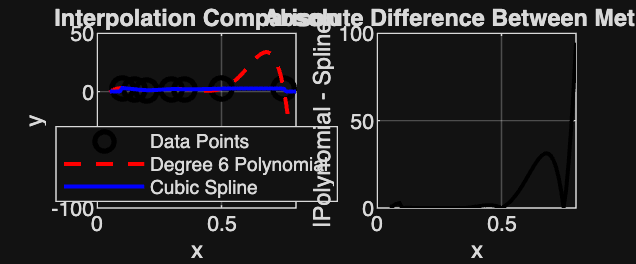

%% Define the data
x_data = [0.1, 0.15, 0.2, 0.3, 0.35, 0.5, 0.75];
y_data = [3.0, 2.0, 1.2, 2.1, 2.0, 2.5, 2.5];

%% Define evaluation points
x_eval = 0.05:0.01:0.8;

%% Construct polynomial interpolant using divided differences
[coeffs_poly, ~] = divided_differences(x_data, y_data);
y_poly = evaluate_dd(x_data, coeffs_poly, x_eval);

%% Construct cubic spline interpolant
% Using natural boundary conditions (second derivatives = 0 at endpoints)
bc_natural = [0, 0, 2];
y_spline = cubic_spline(x_data, y_data, bc_natural, x_eval);

%% Plot comparison
figure('Position', [100, 100, 1200, 500]);

% Plot Both interpolants with data points
subplot(1, 2, 1);
plot(x_data, y_data, 'ko', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName', 'Data Points');
hold on;
plot(x_eval, y_poly, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Degree 6 Polynomial');
plot(x_eval, y_spline, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Cubic Spline');
xlabel('x');
ylabel('y');
title('Interpolation Comparison');
legend('Location', 'best');
grid on;

% Plot Difference between the two methods
subplot(1, 2, 2);
difference = abs(y_poly - y_spline);
plot(x_eval, difference, 'k-', 'LineWidth', 1.5);
xlabel('x');
ylabel('|Polynomial - Spline|');
title('Absolute Difference Between Methods');
grid on;

            - The interpolation comparison reveals dramatically different behaviors between the two methods. The cubic spline remains stable throughout the entire domain, producing a smooth curve that stays within the range of the original data values (1.2 to 3.0). In contrast, the degree 6 polynomial exhibits catastrophic behavior beyond $x = 0.75$, plunging to approximately $-100$ by $x = 0.8$. This extreme divergence is a classic manifestation of the Runge phenomenon, where high-degree polynomials oscillate wildly near boundaries and in sparse data regions. The difference plot shows the methods agree reasonably well for $x < 0.6$, but the discrepancy explodes beyond $x = 0.75$, reaching over 95 at $x = 0.8$. 

    3. After analyzing the previous results, what are your thoughts on polynomial vs piecewise polynomial interpolation?

            - The polynomial's instability stems from its global nature where a single degree 6 polynomial must fit all seven data points simultaneously, giving it enough flexibility to oscillate wildly between and beyond the data points. The cubic spline avoids this through piecewise construction, using different cubic polynomials in each interval while maintaining continuity of the function and its first two derivatives at the points. This approach provides the necessary flexibility to fit the data while maintaining local control, meaning perturbations in one region don't propagate throughout the entire domain. For the dataset analyzed, the cubic spline provides stable, physically plausible results, while the polynomial is essentially unusable beyond $x = 0.75$, making splines the clear choice for most interpolation tasks.